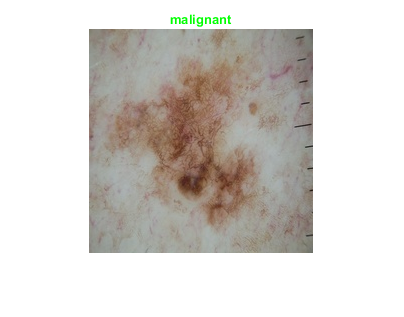

load mini_date2.mat
imds= imageDatastore('E:/LICENTA/BD_Skin_Cancer_Screening/mini_data/test/', ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames' );
labels = netTransfer.classify(imds);
ii = randi(60);
im = imread(imds.Files{ii});
imshow(im);
if labels(ii) == imds.Labels(ii)
   colorText = 'g'; 
else
    colorText = 'r';
end
title(char(labels(ii)),'Color',colorText);

confMat = confusionmat(imds.Labels, labels);
confMat = confMat./sum(confMat,2);
mean(diag(confMat))

ans = 0.9833